# Getting started with iqcToolbox

Welcome! After this script, you will know how to install iqcToolbox, learned some of its basic commands, and hopefully gotten a glimpse of how powerful these analysis tools are.

## Installation

This toolbox is installed with two easy commands:

addpath(fullfile('path_to_iqcToolbox', 'scripts'))
installIqcToolbox

To avoid rerunning this script each time, call the following: 
 >>> 
 clear all 
 load('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 save_added_paths = true; 
 save('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 cd('/home/je29215/iqcToolbox_public/scripts') 
 initializeIqcToolbox 
 >>> 
Issuing the above commands may require admin privileges 


iqcToolbox initialized, try running tests.run_tests_script to test tbx.


`installIqcToolbox` will both download the necessary dependencies, and call `initializeIqcToolbox`, which will add the paths to those dependencies and the directories in iqcToolbox.

*NOTE:*

*Unless otherwise specified, *`installIqcToolbox`* will assume that:*

- *you want to interactively approve of which dependencies are downloaded*

- *you do NOT want to your added paths automatically saved for future MATLAB sessions; continuing with this default choice means you will need to call  *`initializeIqcToolbox`* at the start of every MATLAB session*

*If you want to either of these options changed, call *`installIqcToolbox`* with both input arguments:*

save_added_paths = true;
interactive = false;
installIqcToolbox(save_added_paths, interactive)

To avoid rerunning this script each time, call the following: 
 >>> 
 clear all 
 load('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 save_added_paths = true; 
 save('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 cd('/home/je29215/iqcToolbox_public/scripts') 
 initializeIqcToolbox 
 >>> 
Issuing the above commands may require admin privileges 


iqcToolbox initialized, try running tests.run_tests_script to test tbx.


*NOTE:*

*If you've already installed iqcToolbox, but now want to have all the correct paths permanently saved:*

clear all
cfg_name = which('install_configuration.mat')

cfg_name = '/home/je29215/iqcToolbox_public/configuration/install_configuration.mat'

load(cfg_name)
save_added_paths = true;
save(cfg_name)
initializeIqcToolbox

To avoid rerunning this script each time, call the following: 
 >>> 
 clear all 
 load('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 save_added_paths = true; 
 save('/home/je29215/iqcToolbox_public/configuration/install_configuration.mat') 
 cd('/home/je29215/iqcToolbox_public/scripts') 
 initializeIqcToolbox 
 >>> 
Issuing the above commands may require admin privileges 


iqcToolbox initialized, try running tests.run_tests_script to test tbx.


*Depending on your system, you may need admin rights for the added paths to be saved. For example, in a Linux system, start a matlab session with *

`>> sudo matlab`

*and repeat the previous MATLAB commands.*

*NOTE:*

*The only necessary dependencies for this toolbox are *[yalmip](https://yalmip.github.io)*, *[SDPT3](https://github.com/Kim-ChuanToh/SDPT3/)*, and *[LPSOLVE](http://lpsolve.sourceforge.net/5.5/)*.  You may benefit from having other Semidefinite Program (SDP) solvers besides SDPT3.  This might include *[SeDuMi](https://github.com/sqlp/sedumi)*, *[mosek](https://www.mosek.com/)*, or *[csdp](https://github.com/coin-or/Csdp)*.  The latter two solvers are capable of leveraging parallel computing resources; mosek is free for academic use, csdp is free for general use (EPL 2.0 license).*

## Building and analyzing uncertain systems

Let's start using iqcToolbox's most important functions. 

### Analyzing a system with no uncertainties

Consider the system :


$$\displaystyle G: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 \cr 3/4 & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1 & 0}\right] & x(k)}$$


Since the A-matrix is Schur (all eigenvalues are within the unit circle), we know the system is stable.  Let's check this:

a = [0, 3/4; 3/4, 0];
b = [1; 0];
c = [1, 0];
d = 0;
timestep = -1;   % An unspecified timestep
g = ss(a, b, c, d, timestep);
stable = isstable(g)

stable = logical
   1


performance = norm(g, 'inf')   % Given a stable system, this measures a systems H-infinity norm, or l2-induced performance

performance = 2.2857

We can get this same information by converting the `ss` object `g` into a `Ulft` object and conducting IQC analysis on it:

g_lft = toLft(g)

g_lft = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  0 uncertainties forming a   0 x   0 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 

% or
g_lft = toLft(a, b, c, d, timestep)

g_lft = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  0 uncertainties forming a   0 x   0 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 

result = iqcAnalysis(g_lft)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: 2.2857
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×1 MultiplierDeltaDefault]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[2×2 sdpvar]  [2×2 sdpvar]}
                      valid: 1
                      debug: [1×1 struct]


result.valid   % This boolean expresses if the LFT is robustly stable

ans = logical
   1


result.performance   % This returns the upper-bound on a LFT's specified performance (default: l2-induced)

ans = 2.2857

### Analyzing an uncertain system: Part I

But what if there was uncertainty in the system model? Consider the case where our A-matrix could have some error in it's values:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


We could prove that this is stable for all possible values of `delta` (robustly stable) by solving for the eigenvalues of the A-matrix and showing they are within the unit-circle.  IQC analysis can also prove robust stability with the following:

dims = 1;
lower_bound = -1/2;
upper_bound = 1/2;
del = DeltaSlti('del', dims, lower_bound, upper_bound)  % a 1x1 Static, Linear, Time-Invariant (SLTI) uncertainty with the given bounds

del =      del     is a   1 x 1     SLTI uncertainty 
              within the bounds: [-0.5, 0.5] 

a_del = [0, 3/4 + del; 3/4 - del, 0];  % the uncertain A-matrix 
g_del = toLft(a_del, b, c, d, timestep)  % the uncertain system defined with the uncertain A-matrix

g_del = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del     is a   2 x 2     SLTI uncertainty 
              within the bounds: [-0.5, 0.5] 

result = iqcAnalysis(g_lft)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: 2.2857
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×1 MultiplierDeltaDefault]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[2×2 sdpvar]  [2×2 sdpvar]}
                      valid: 1
                      debug: [1×1 struct]


result.valid   % Indicates if the system robustly stable

ans = logical
   1


result.performance  % Bound on the worst case l2-induced norm for any admissible delta

ans = 2.2857

### Analyzing an uncertain system: Part II

But what if our uncertainty were time-varying? In other words, consider the (now time-varying) system:


$$G_{\delta, LTV}: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta(k) \cr 3/4 - \delta(k) & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta(k) \in [-1/2, 1/2] \mbox{ for all } k \in \mathbb{N}_0$$


In this case, we now make a time-varying, rather than time-invariant, `delta`:

del_ltv = DeltaSltv('del', dims, lower_bound, upper_bound)  % A Static, Linear, Time-Varying (SLTV) uncertainty

del_ltv =      del     is a   1 x 1     SLTV uncertainty 
              within the bounds: [-0.5, 0.5] 

a_del_ltv = [0, 3/4 + del_ltv; 3/4 - del_ltv, 0];
g_del_ltv = toLft(a_del_ltv, b, c, d, timestep)

g_del_ltv = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del     is a   2 x 2     SLTV uncertainty 
              within the bounds: [-0.5, 0.5] 

result = iqcAnalysis(g_del_ltv)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: Inf
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×2 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[2×2 sdpvar]  [2×2 sdpvar]}
                      valid: 0
                      debug: [1×1 struct]


result.valid  % This will be false, because the LFT is not robustly stable

ans = logical
   0


result.performance  % As this is not robustly stable, there is no upper-bound on the l2-induced performance

ans = Inf

An inability to conclude robust stability is expected. Consider the following admissible sample of `del_ltv`:


$$\delta(k) = \left\{\matrix{1/2 \mbox{ for odd } k \cr -1/2 \mbox{ for even } k } $$


The resulting system is unstable. Look, for instance, at the system output given a non-zero initial condition and a zero input signal:

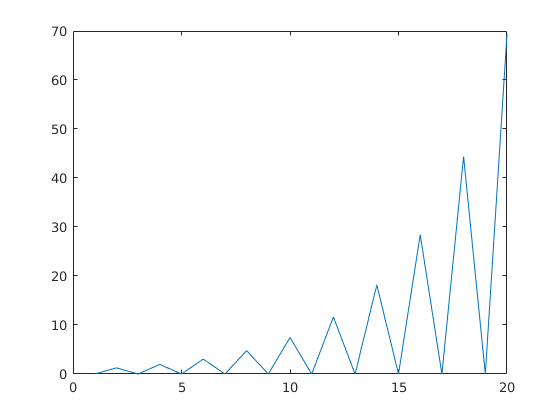

a_odd =  [0, 3/4 + 1/2; 3/4 - 1/2, 0];
a_even = [0, 3/4 - 1/2; 3/4 + 1/2, 0];
a_k = {a_even, a_odd};
x = [0; 1];
for i = 1:20
    y(i) = c * x;
    x = a_k{mod(i, 2) + 1} * x;
end
figure
plot(y)

Here we see that the null result from IQC analysis on `G_del_ltv`  was consistent with the system NOT being robustly stable. However, when we narrow the uncertainty set to only consist of *time invariant *uncertainties (holding all other properties the same)*, *IQCs can leverage that additional information and correctly conclude robust stability. 

### Analyzing an uncertain system: Part III

A key advantage of IQC analysis is the broad library of IQCs that can characterize sets of uncertainties.  In the last example, we saw that the uncertain system `G_del` was robustly stable if the uncertainty were time invariant, but NOT robustly stable if the uncertainty were time varying. But what if `del` were time-varying and it had a bound on the rate-of-change?  There are IQCs to express that uncertainty set too.

upper_rate = 1/4;
lower_rate = -1/4;
del_ltv_rate = DeltaSltvRateBnd('del', dims, lower_bound, upper_bound, lower_rate, upper_rate);   % A Static, Linear, Time Varying, Rate Bounded uncertainty, with bounds and rates as given
a_del_ltv_rate = [0, 3/4 + del_ltv_rate; 3/4 - del_ltv_rate, 0];
g_del_ltv_rate = toLft(a_del_ltv_rate, b, c, d, timestep)

g_del_ltv_rate = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del     is a   2 x 2   SLTV, rate-bounded uncertainty 
              within the bounds: [-0.5, 0.5] 
              whose rate-of-change is within: [-0.2, 0.2] 

result = iqcAnalysis(g_del_ltv_rate)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: 4.2696
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×2 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[6×6 sdpvar]  [6×6 sdpvar]}
                      valid: 1
                      debug: [1×1 struct]


result.valid

ans = logical
   1


result.performance

ans = 4.2696

Here we see that the resulting system is robustly stable.  If we set the rate bounds to be zero, we recover the results pertaining to time-invariant uncertainties.

del_ltv_rate_zero = DeltaSltvRateBnd('del', dims, lower_bound, upper_bound, 0, 0);
a_del_ltv_rate_zero = [0, 3/4 + del_ltv_rate_zero; 3/4 - del_ltv_rate_zero, 0];
g_del_ltv_rate_zero = toLft(a_del_ltv_rate_zero, b, c, d, timestep)

g_del_ltv_rate_zero = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del     is a   2 x 2   SLTV, rate-bounded uncertainty 
              within the bounds: [-0.5, 0.5] 
              whose rate-of-change is within: [0.0, 0.0] 

result = iqcAnalysis(g_del_ltv_rate_zero)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: 2.2862
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×2 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[6×6 sdpvar]  [6×6 sdpvar]}
                      valid: 1
                      debug: [1×1 struct]


result.valid

ans = logical
   1


result.performance

ans = 2.2862

 Additionally, if we set the rate bounds to be too big, we recover the results pertaining to time-varying, arbitrarily fast uncertainties.

del_ltv_rate_fast = DeltaSltvRateBnd('del', dims, lower_bound, upper_bound, -1, 1);
a_del_ltv_rate_fast = [0, 3/4 + del_ltv_rate_fast; 3/4 - del_ltv_rate_fast, 0];
g_del_ltv_rate_fast = toLft(a_del_ltv_rate_fast, b, c, d, timestep)

g_del_ltv_rate_fast = A [ 0,  1]-eventually periodic LFT with   1 outputs,   1 inputs,   2 states, and
  1 uncertainties forming a   2 x   2 uncertainty block
********************************************************************************
**********************************   DELTAS   **********************************
     DelayZ  is a   2 x 2       delay operator 
              with an undefined timestep 
     del     is a   2 x 2   SLTV, rate-bounded uncertainty 
              within the bounds: [-0.5, 0.5] 
              whose rate-of-change is within: [-1.0, 1.0] 

result = iqcAnalysis(g_del_ltv_rate_fast)


 num. of constraints =  4
 dim. of sdp    var  =  5,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e+00|1.1e+01|5.0e+02|-1.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.884|1.000|1.0e+00|1.0e-01|5.3e+01|-8.546340e+00 -1.912273e+01| 0:0:00| chol  1  1 
 2|1.000|1.000|2.5e-06|1.0e-02|6.9e+00|-3.734730e+00 -1.060283e+01| 0:0:00| chol  1  1 
 3|1.000|0.887|1.3e-06|2.0e-03|8.3e-01|-4.609905e+00 -5.429355e+00| 0:0:00| chol  1  1 
 4|0.961|1.000|4.4e-07|1.0e-04|4.2e-02|-5.197589e+00 -5.238348e+00| 0:0:00| chol  1  1 
 5|0.985|0.988|9.1e-09|1.1e-05|5.7e-04|-5.224152e+00 -5.224628e+00| 0:

result = struct with fields:
                performance: Inf
                    ellipse: NaN
        state_amplification: NaN
        multiplier_combined: [1×1 MultiplierDeltaCombined]
          multipliers_delta: [1×2 MultiplierDelta]
    multipliers_disturbance: [1×1 MultiplierL2]
    multipliers_performance: [1×1 MultiplierL2Induced]
              kyp_variables: {[6×6 sdpvar]  [6×6 sdpvar]}
                      valid: 0
                      debug: [1×1 struct]


result.valid

ans = logical
   0


result.performance

ans = Inf

The ability to flexibly and modularly express a variety of uncertainties is a core utility of IQC analysis. While the available IQCs in the literature is vast, not all are included in iqcToolbox.  These can be added to iqcToolbox as subclasses of the abstract `Delta `class (more on this in the section on Delta).